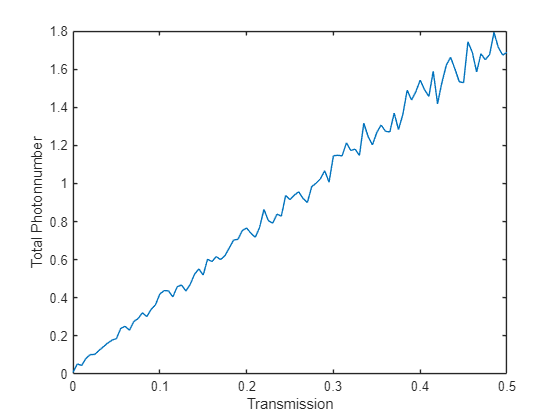

% script to check the photon number linearity of a homodyne series measured
% with the Rotationstage Option

% load the data
Dir = "D:\Data\Tests\12.12.24 TestSeries\0i5 percent Series";
Files = QST.File_Managment.getFilePaths(Dir);
[~,~,Ext] = fileparts(Files);
Files = Files(strcmp(Ext,".mat"));

nFiles = length(Files);
[T,nTherm,nCoherent] = deal(zeros([1,nFiles]));
for i = 1:nFiles
    T(i) = QST.Variable_Managment.getMetaDataFromString(Files(i),"T[0-9]+[.]?[0-9]*","[0-9]+[.]?[0-9]*",[],@double);
    nTherm(i) = QST.Variable_Managment.getVariableFromFilePath(Files(i),["Wigner_10Sets_1Rho_500It.nTherm"]);
    nCoherent(i) = QST.Variable_Managment.getVariableFromFilePath(Files(i),["Wigner_10Sets_1Rho_500It.nCoherent"]);
end
nTotal = nTherm+nCoherent;

% check linearity
plot(T,nTotal)
xlabel("Transmission");
ylabel("Total Photonnumber");

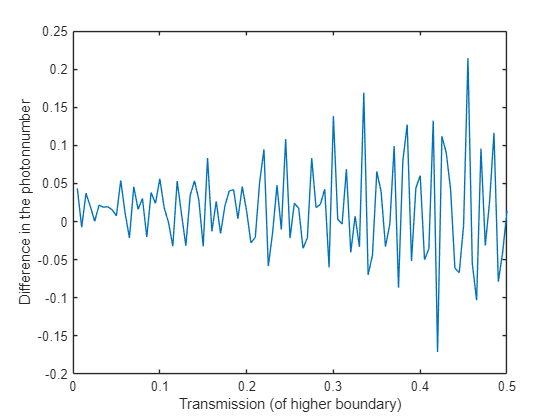

% -> seems to be more or less linear

% check if the steps are equidistant
Photondifferences = diff(nTotal);
plot(T(2:end),Photondifferences)
xlabel("Transmission (of higher boundary)");
ylabel("Difference in the photonnumber");

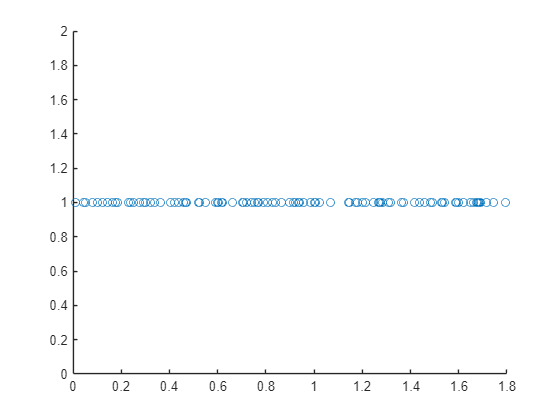

% the jumps are quite drastic between 0.1 and 0.3 -> this is not 
% equidistant

% different view on it
Constant = ones([1,nFiles]);
scatter(nTotal,Constant)